zad1

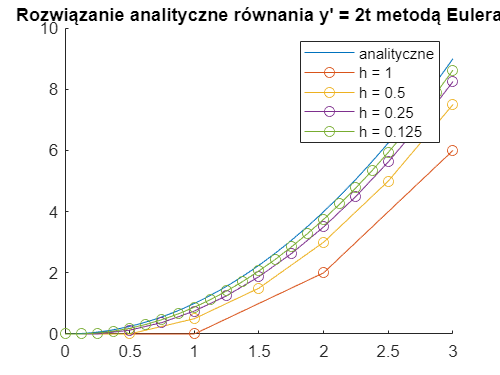

clear all;
close all;

h1 = 1;
h2 = 0.5;
h3 = 0.25;
h4 = 0.125;

t0 = linspace(0, 3, 300);
y = t0.^2;
t1(1) = 0;
y1(1) = 0;
t2(2) = 0;
y2(1) = 0;
t3(1) = 0;
y3(1) = 0;
t4(1) = 0;
y4(1) = 0;

i = 1;
while t4(i) < 3
    t1(i+1) = t1(i) + h1;
    y1(i+1) = y1(i) + 2*h1*(t1(i));
    t2(i+1) = t2(i) + h2;
    y2(i+1) = y2(i) + 2*h2*(t2(i));
    t3(i+1) = t3(i) + h3;
    y3(i+1) = y3(i) + 2*h3*(t3(i));
    t4(i+1) = t4(i) + h4;
    y4(i+1) = y4(i) + 2*h4*(t4(i));
    i = i + 1;
end

hold on
plot(t0, y, t1, y1, '-o', t2, y2, '-o', t3, y3, '-o', t4, y4, '-o')
legend("analityczne", "h = 1", "h = 0.5", "h = 0.25", "h = 0.125")
title("Rozwiązanie analityczne równania y' = 2t metodą Eulera")
xlim([0 3])
hold off

zad2

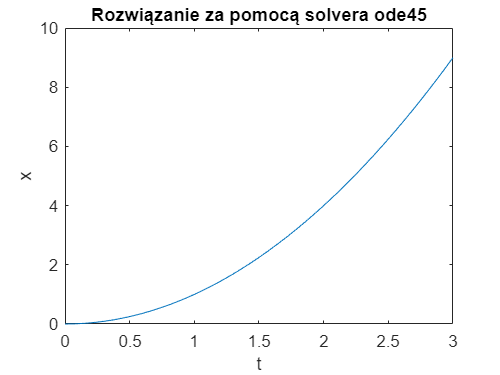

clear all; 
close all;

h = [0, 3];                             % przedział czasowy
x0 = 0;                                 % warunek początkowy
[t, x] = ode45(@func_zad1, h, x0);
plot(t,x)
xlabel('t')
ylabel('x')
title('Rozwiązanie za pomocą solvera ode45')

zad3

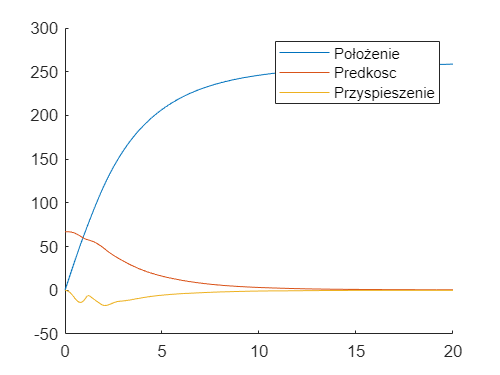

clear all; 
close all;
global w3;
options = odeset('OutputFcn',@hamownik_out,'Refine',1);
[T,Y] = ode45(@hamownik,[0 20],[0 67 0 0 0 0],options);

hold on
plot(T,Y(:,1));
plot(T,Y(:,2));
plot(T,w3);

legend("Położenie", "Predkosc", "Przyspieszenie")